# Atividade 07_04

Otávio Baziewicz Filho - 1942808

clc; clear; close all; 

## Detecção de bordas usando o método Kirsch

Implemente e teste o Kirsch na imagem de sua preferência. É simples: depois de definir todas as oito máscaras, convoluir cada uma com a imagem é moleza, é pra isso que existe a função imfilter. A dica é armazenar cada imagem convoluída em uma página diferente (dimensão 3) da mesma matriz. Por exemplo: kirschT(:,:,1) recebe o resultado da convolução da imagem de entrada com a máscara K0; kirschT(:,:,2) recebe o resultado da convolução da imagem de entrada com a máscara K1, e assim por diante. Com isso, será possível encontrar o máximo das saídas das oito máscaras usando a seguinte sintaxe: kirsch = max(kirschT,[],3);

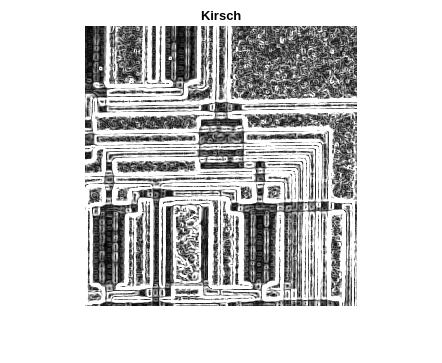

img = imread("circuit.tif");
dImg = im2double(img);

k0 = [-3,-3,5;-3,0,5;-3,-3,5];
kT(:,:,1) = imfilter(dImg, k0,  "replicate");

k1 = [-3,5,5;-3,0,5;-3,-3,-3];
kT(:,:,2) = imfilter(dImg, k1,  "replicate");

k2 = [5,5,5;-3,0,-3;-3,-3,-3];
kT(:,:,3) = imfilter(dImg, k2,  "replicate");

k3 = [5,5,-3;5,0,-3;-3,-3,-3];
kT(:,:,4) = imfilter(dImg, k3,  "replicate");

k4 = [5,-3,-3;5,0,-3;5,-3,-3];
kT(:,:,5) = imfilter(dImg, k4,  "replicate");

k5 = [-3,-3,-3;5,0,-3;5,5,-3];
kT(:,:,6) = imfilter(dImg, k5,  "replicate");

k6 = [-3,-3,-3;-3,0,-3;5,5,5];
kT(:,:,7) = imfilter(dImg, k6,  "replicate");

k7 = [-3,-3,-3;-3,0,5;-3,5,5];
kT(:,:,8) = imfilter(dImg, k7,  "replicate");

kirsch = max(kT, [], 3);

figure, imshow(kirsch)
title("Kirsch")